# ***Invisible watermarking for digital images***

## ***Generating the input image DCT***

Let's start with an un-watermarked image.

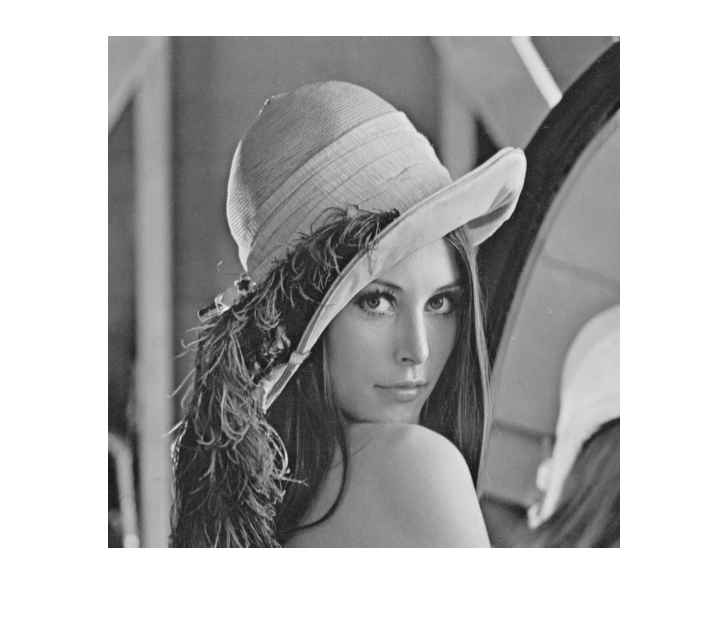

im = imread('lena.tiff');
figure, imshow(im)

We'll apply a quantization matrix for compression. The standard quantization matrix is

QP = [16  11  10  16  24  40  51  61;
      12  12  14  19  26  58  60  55;
      14  13  16  24  40  57  69  56;
      14  17  22  29  51  87  80  62;
      18  22  37  56  68 109 103  77;
      24  35  55  64  81 104 113  92;
      49  64  78  87 103 121 120 101;
      72  92  95  98 112 100 103  99];
  

Then find the DCT as per normal.

im_dct = blockproc(double(im), [8 8], @(b) round(dct2(b.data)));

Scale the values by the (scaled) quantization matrix.

scale_f = 0.5;
QP_scale = QP .* scale_f;
quant_dct= @(block_struct) round(block_struct.data ./ QP_scale) .* QP_scale;
im_quant = blockproc(im_dct, [8 8], quant_dct);

## Adding the watermark to the DCT

The watermark will be a string of characters. Each character will be encoded as a digit 0->26 corresponding to its frequency in the english alphabet.

letter_freq = {' ', 'e', 't', 'a', 'o', 'i', 'n', 's', 'h', 'r', 'd', 'l', 'c', ...
               'u', 'm', 'w', 'f', 'g', 'y', 'p', 'b', 'v', 'k', 'j', 'x', 'q', 'z' };
letter_offset = containers.Map(letter_freq, [0:size(letter_freq, 2)-1]);

Now we can convert our watermark phrase into a set of minimal offsets.

wm = 'Hello ELEC 483!';
wm = lower(wm);

% Loop through per character and make a vector from mapped values.
% Characters not in the map get 0.

## == Leftover for reference ==

wm = zeros(size(im_quant));
wm(1, 1) = 30;
% wm = ones(size(im_quant)) .* 26
im_wm = im_quant + wm

im_wm =    1.0e+03 *

    1.3020    0.0055    0.0050         0         0         0         0         0    1.2560    0.0165         0    0.0080   -0.0120         0         0         0    1.2400    0.0110   -0.0050   -0.0080         0         0         0         0    1.2240         0    0.0050         0         0         0         0         0    1.2560   -0.0275    0.0050         0         0         0         0         0    1.3520   -0.0220   -0.0050    0.0080         0         0         0         0    1.3280    0.0330
    0.0060         0         0   -0.0095         0         0         0         0    0.0120         0         0    0.0095         0         0         0         0    0.0120         0         0   -0.0095         0         0         0         0    0.0060         0         0         0         0         0         0         0    0.0060         0   -0.0070         0         0         0         0         0         0         0         0         0         0         0         0       

nonzeroCoeff = 45428

Reconstruct the image and determine the PSNR.

im_r = blockproc(im_quant, [8 8], @(b) idct2(b.data));
psnr = 10 * log10(255 * 255 / mean(mean((double(im) - im_r).^2)))

psnr = 37.8818

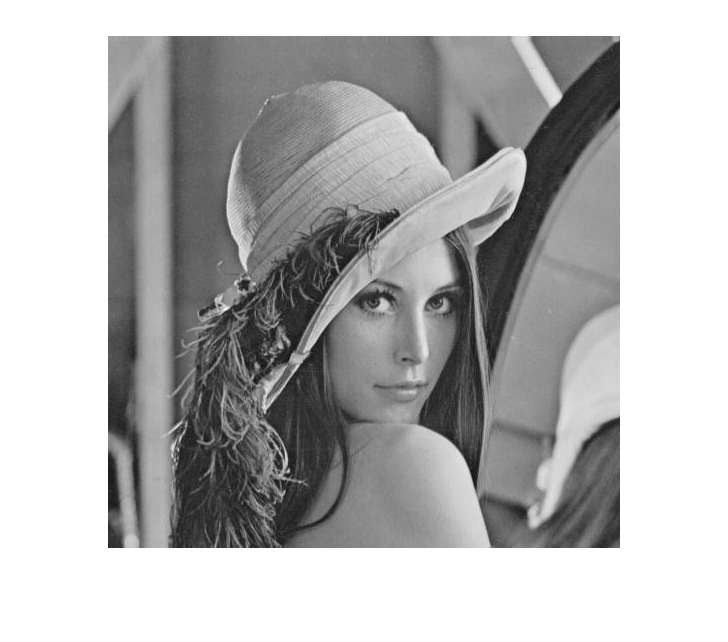

figure, imshow(uint8(im_r))

im_wm_r = blockproc(im_wm, [8 8], @(b) idct2(b.data));
psnr = 10 * log10(255 * 255 / mean(mean((double(im) - im_wm_r).^2)))

psnr = 37.8805

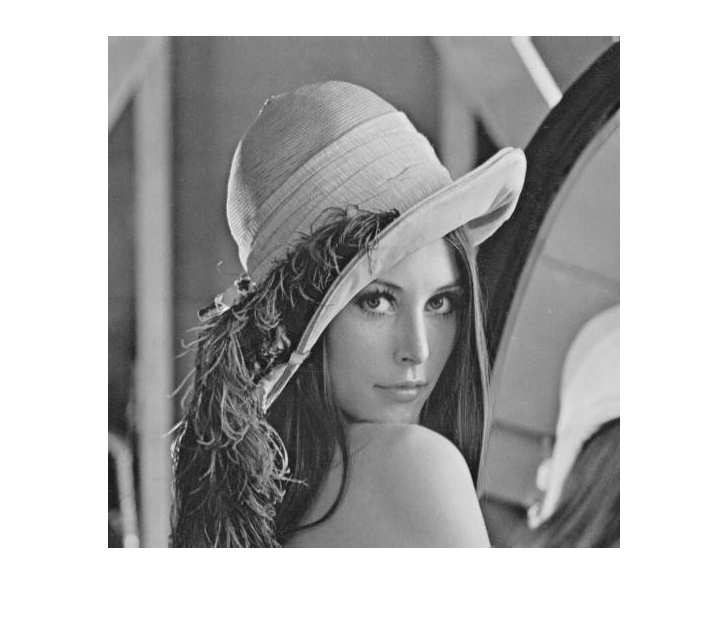

figure, imshow(uint8(im_wm_r))